# Geometric interpretation of regularized least squares

- Ordinary Least Squares:    $\textrm{𝐱}̂={\textrm{argmin}}_{\mathbf{x}} ||\textrm{𝐛}-\textrm{𝐀𝐱}{\left\|\right.}_2^2 \;$

## Ridge Regression:             

- Regularized least squares:     $\textrm{𝐱}̂={\textrm{argmin}}_{\mathbf{x}} ||\textrm{𝐛}-\textrm{𝐀𝐱}{\left\|\right.}_2^2 +\textrm{𝜆}||\textrm{𝐱}{\left\|\right.}_2^{2\;}$

- Equivalent constrained opt:    $\textrm{𝐱}̂={\textrm{argmin}}_{\mathbf{x}} ||\textrm{𝐛}-\textrm{𝐀𝐱}{\left\|\right.}_2^2 \;\;\textrm{subject}\;\textrm{to}\;\;\;||\textrm{𝐱}{\left\|\right.}_2^{2\;} \le c$

## LASSO Regression:

- Regularized least squares:     $\textrm{𝐱}̂={\textrm{argmin}}_{\mathbf{x}} ||\textrm{𝐛}-\textrm{𝐀𝐱}{\left\|\right.}_2^2 +\textrm{𝜆}||\textrm{𝐱}{\left\|\right.}_1$

- Equivalent constrained opt:    $\textrm{𝐱}̂={\textrm{argmin}}_{\mathbf{x}} ||\textrm{𝐛}-\textrm{𝐀𝐱}{\left\|\right.}_2^2 \;\;\textrm{subject}\;\textrm{to}\;\;\;||\textrm{𝐱}{\left\|\right.}_1^{\;} \le c$

**Plot constraint and error contours for regression with 2 features **

- Compute the mean squared error MSE for all $x_1$ and $x_2$ and plot the MSE contours.

- Increase the MSE until the constraint is satisfied

- **Ridge**: solution not sparse, **LASSO**: solution sparse

## Generate data

addpath(genpath(pwd))

m = 10;    % number of measurements (time steps)
D = 2;     % number of features (library terms)

rng(1) % specify seed random number generator
A = randn(m,D);    % Matrix of possible predictors              
x = [0.4; 0.9];    % Coefficients
b = A*x + 0.01*randn(m,1); % Observations (with noise)

% ordinary least squares solution
xOLS = (A'*A)^-1*A'*b;

% Loss function 
mse = norm(A*xOLS-b,2); % OLS mean square error
c = 0.5; % constraint
levelSetsMSE = lsRLS(A,b,c); % least squares error contours: ||b-Ax||=const


### Plot Ridge Regression

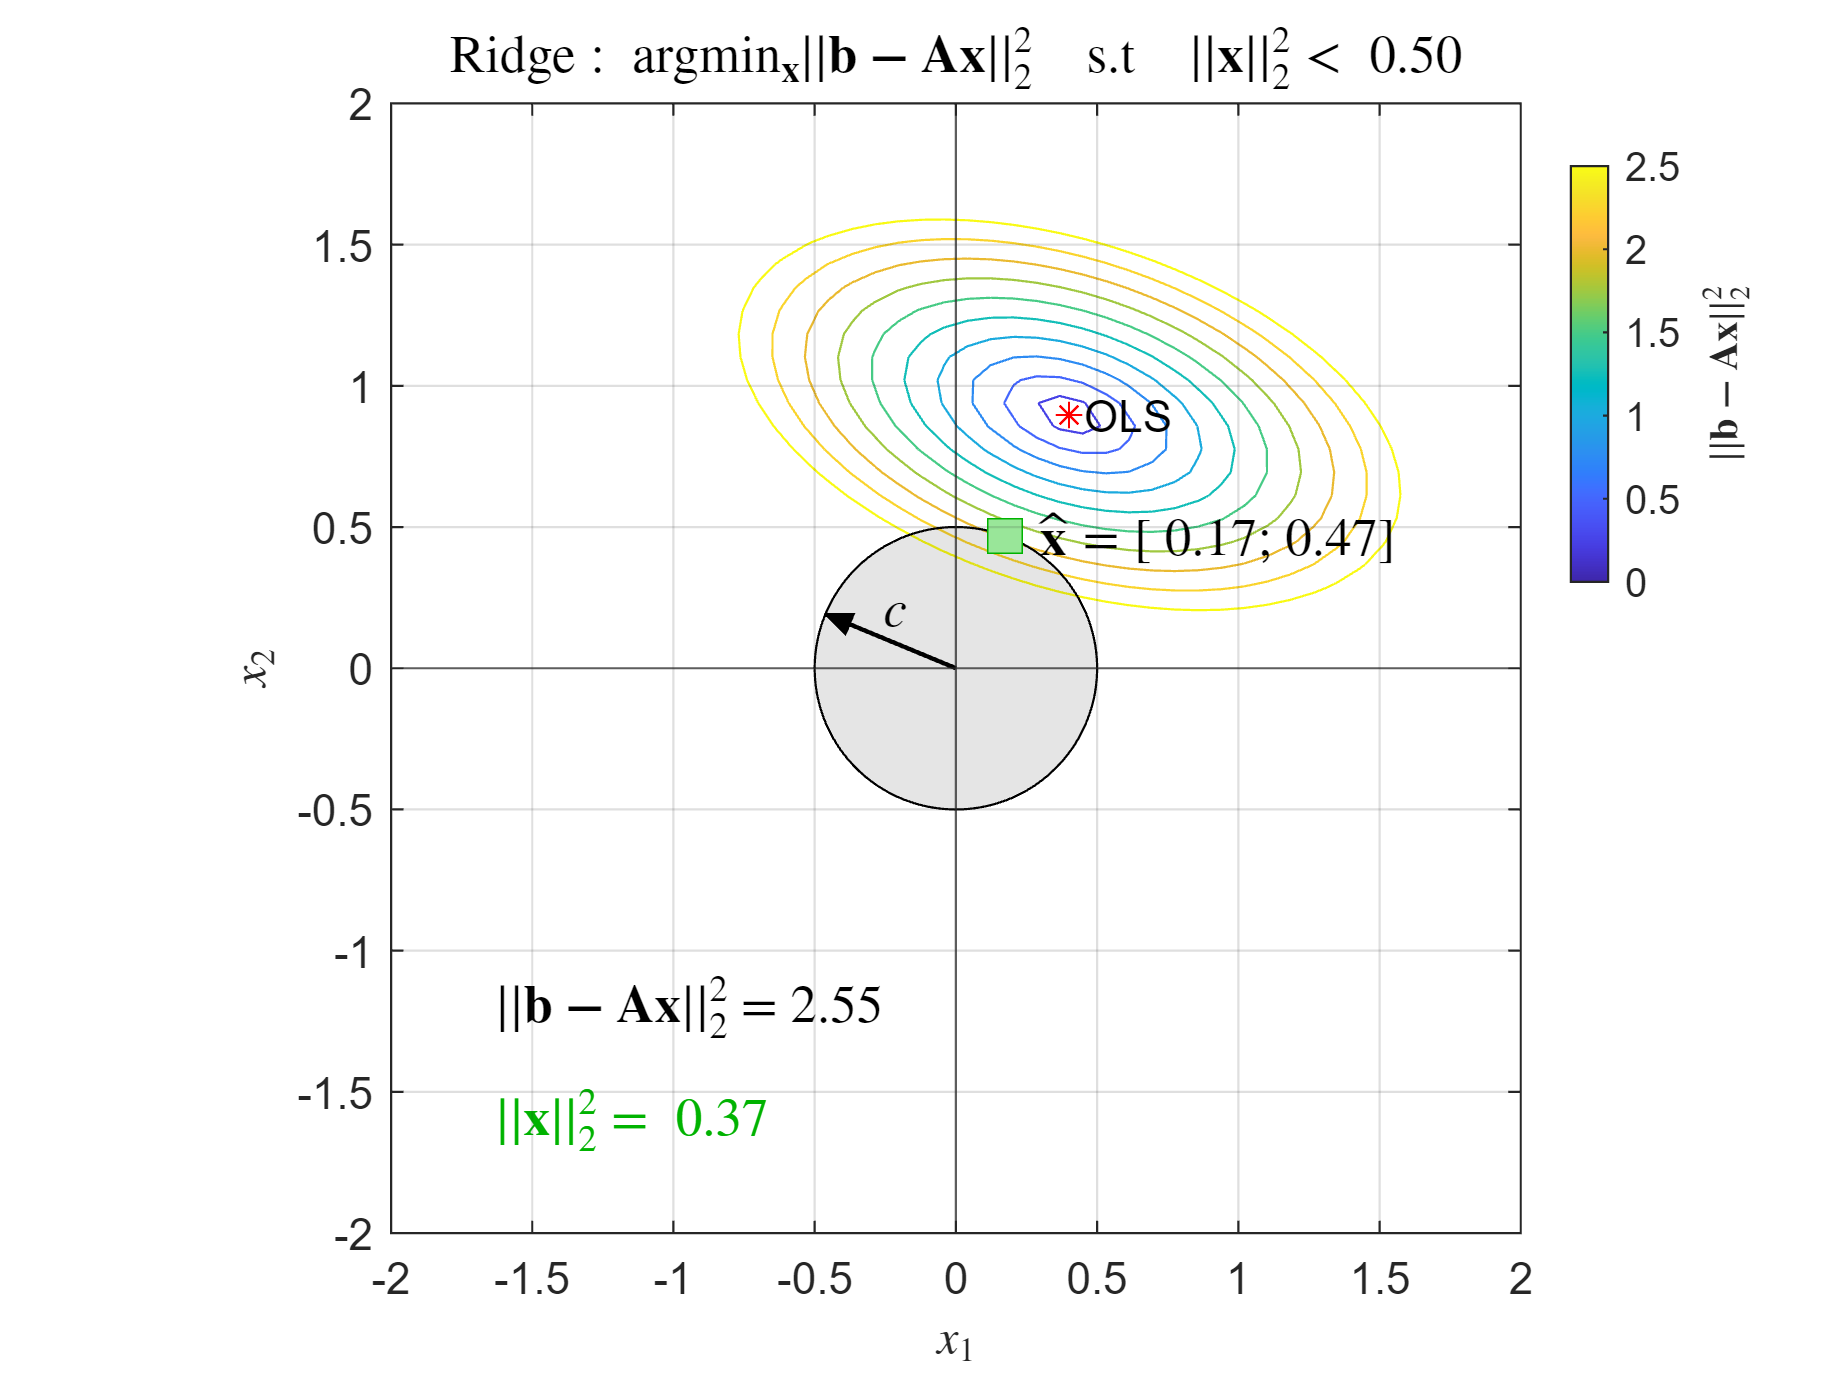

mLS = 2.55; % max MSE contour: ||b-Ax||=const=mLS

plotRR(xOLS,mLS,c,levelSetsMSE)

### Plot LASSO Regression

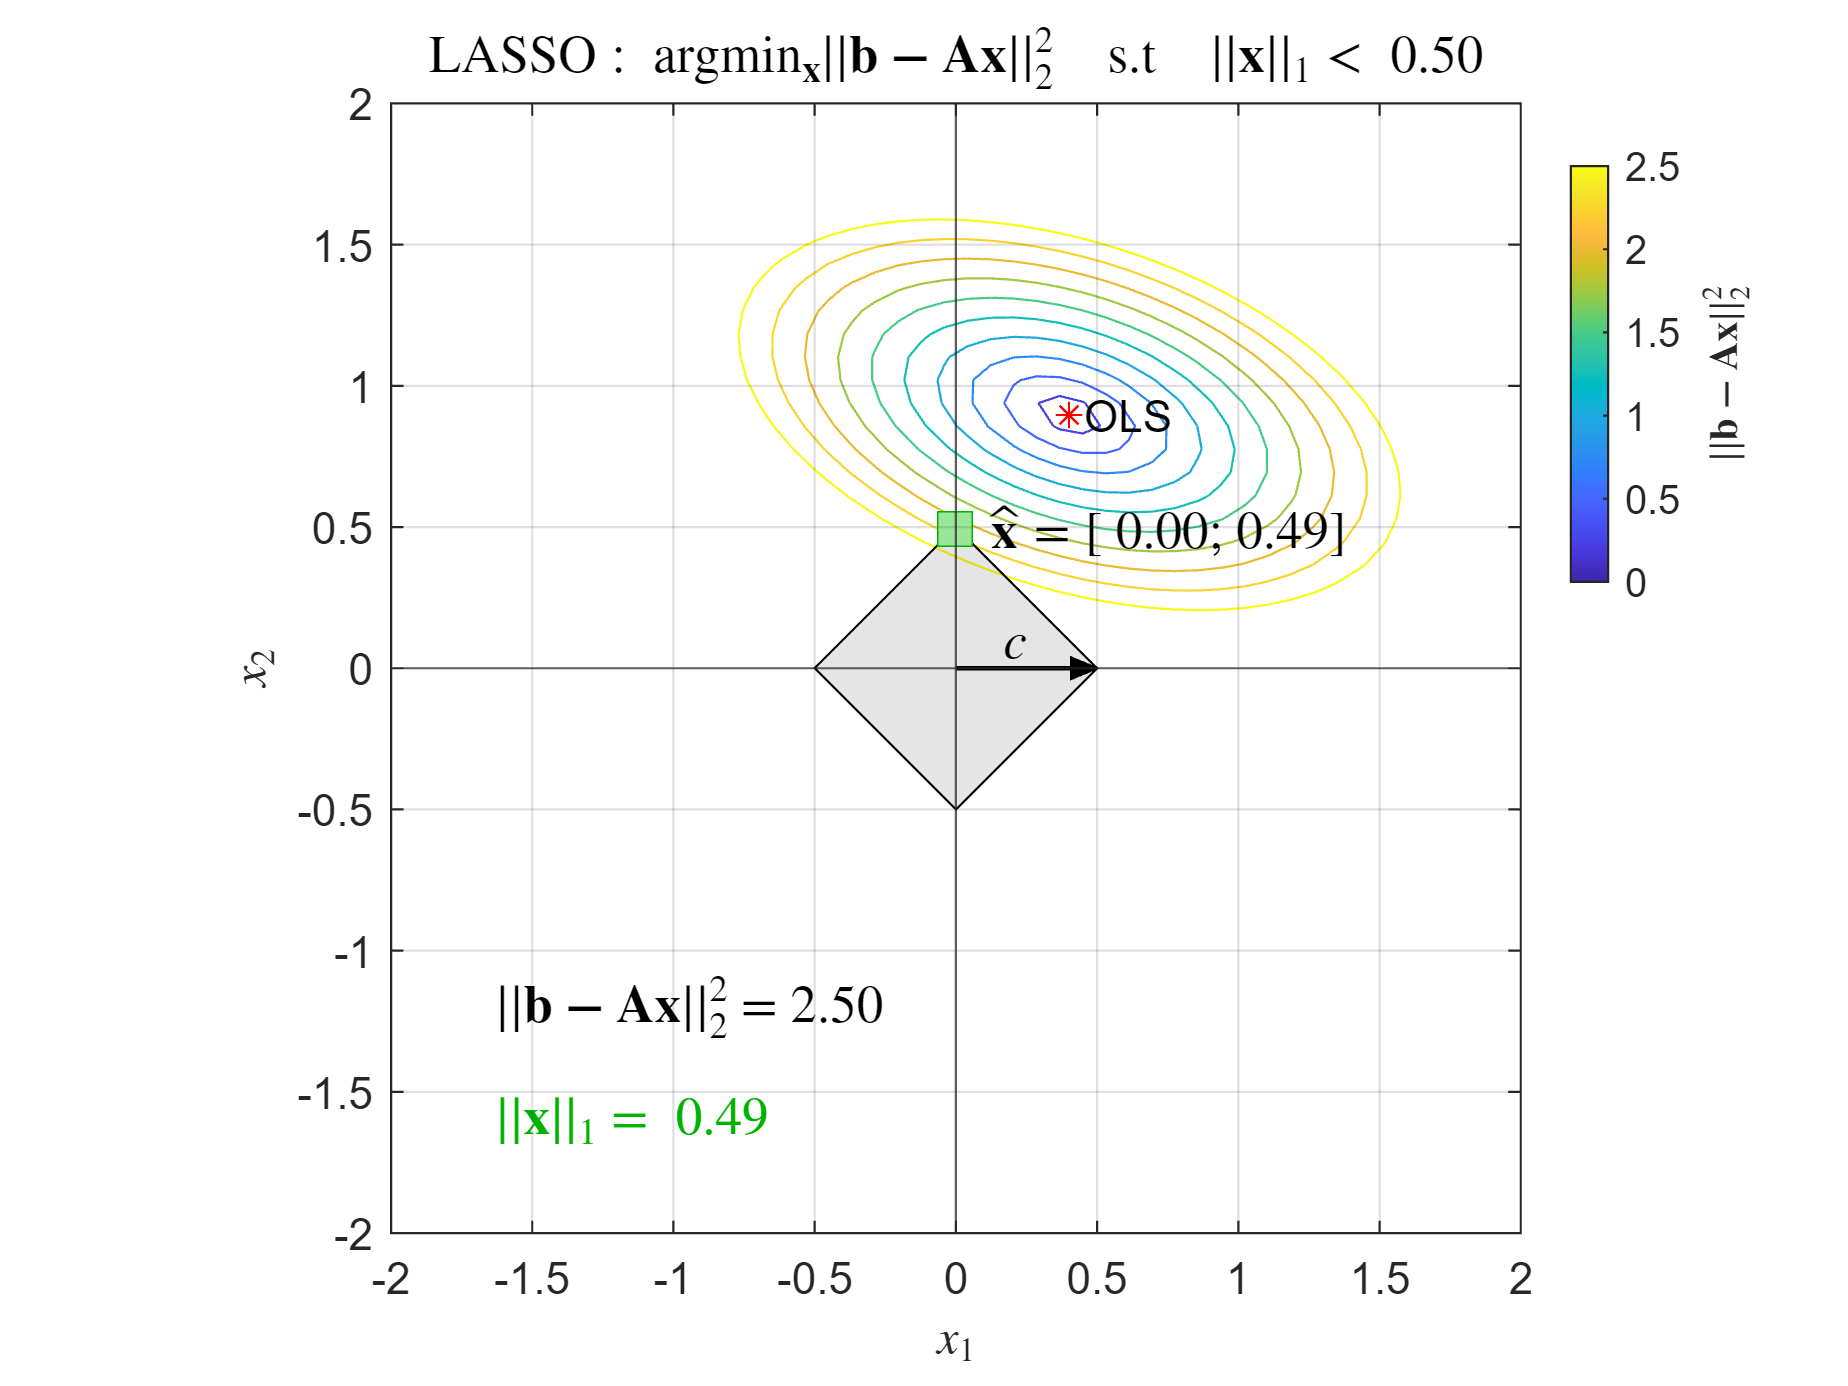

mLS = 2.5; % max MSE contour: ||b-Ax||=const=mLS 

plotLASSO(xOLS,mLS,c,levelSetsMSE)